# Data Prediction

load fisheriris.mat
[~, ~, s] = unique(species);
y = meas(:,4); % Response variable
rng(0);%seed
features = [meas(:,1:3),s,meas(:,1)+0.2*randn(150,1), randn(150,1)];%With redundant feature + noise

### Split Dataset(Training)

train_x = features(1:2:end,:);
train_y = y(1:2:end,:);

### Validation set

To be used for tuning hyper parameters

validate_x = features(2:4:end,:);
validate_y = y(2:4:end,:);

### Testing set

test_x = features(4:4:end,:);
test_y = y(4:4:end,:);

## Create Linear Model

%4th parameter is 4 since it contains the categories in the feature set
mdl = fitlm(train_x, train_y, "CategoricalVars",[4]);
mdl

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)     -0.64735     0.24019     -2.6952      0.008886
    x1              -0.09134    0.099204    -0.92073        0.3605
    x2               0.29863    0.062961       4.743    1.1431e-05
    x3               0.27685    0.059804      4.6293    1.7361e-05
    x4_2             0.65501     0.15499      4.2261    7.3544e-05
    x4_3              1.0534     0.20785      5.0682    3.3829e-06
    x5             -0.022648    0.079215    -0.28591       0.77583
    x6             -0.033905

pdct_lm = predict(mdl, test_x);

### Measure Error

%Mean square error
MSE = mean((test_y - pdct_lm).^2);
MSE

MSE = 0.0306

### Plot

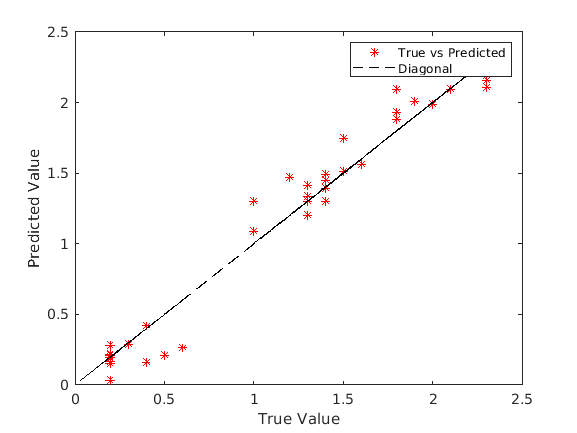

figure(1);
plot(test_y, pdct_lm, 'r*');
xlabel('True Value');
ylabel('Predicted Value');
rg = [min(test_y, pdct_lm), max(test_y, pdct_lm)];%Regression line
hold on
plot(rg,rg,'k--');
legend('True vs Predicted', 'Diagonal');
hold off

## Pearson Correlation test

[r, p] = corr(test_y, pdct_lm)

r = 0.9761

p = 8.7520e-25

### Remove features with High P-value(>0.05) using Stepwise Regression

mdl = stepwiselm(train_x, train_y,"constant","Upper","linear","CategoricalVars",[4]);

1. Adding x4, FStat = 534.8125, pValue = 6.210477e-44
2. Adding x2, FStat = 27.213, pValue = 1.72503e-06
3. Adding x3, FStat = 15.8445, pValue = 0.00016586
4. Adding x1, FStat = 5.2375, pValue = 0.025172


mdl

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.67337     0.24067    -2.7979     0.0066615
    x1             -0.11989    0.052386    -2.2886      0.025172
    x2              0.31872     0.06164     5.1706    2.1708e-06
    x3              0.27098    0.059938     4.5211    2.4843e-05
    x4_2            0.69158     0.15465     4.4719    2.9699e-05
    x4_3             1.0856     0.20851     5.2066    1.8899e-06


Number of observations: 75, Error degrees of freedom: 69
Root Mean Squared Error: 0.152
R-squared: 0.965,  Adjusted R-Squared: 0.963
F-statistic vs. cons

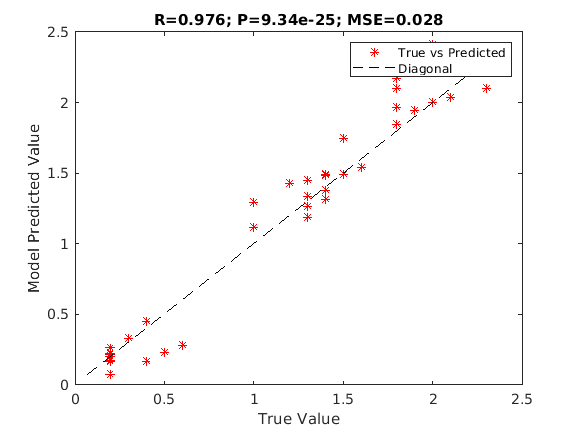

pdct_slm = predict(mdl, test_x);
figure(2);
EstimationErrorPlot(pdct_slm, test_y);

## For the case of non-linear Highly Discontinued data

% Problem case
mns = mean(features(1:2:end,:));
partitioned_y = features(:,1)+2*(features(:,1)>mns(1))+features(:,2)+10*(features(:,2)>mns(2))+ ...
    features(:,3)+50*(features(:,3)>mns(3))+features(:,4)+100*(features(:,4)>mns(4));
subset = features(:,1:4);
train_x = subset(1:2:end,:);
validate_x = subset(2:4:end,:);
test_x = subset(4:4:end,:);
train_y = partitioned_y(1:2:end);
validate_y = partitioned_y(2:4:end);
test_y = partitioned_y(4:4:end);
mdl = stepwiselm(train_x, train_y,"constant","Upper","linear","CategoricalVars",[4]);

1. Adding x4, FStat = 1136.6826, pValue = 3.4386925e-55
2. Adding x3, FStat = 33.9746, pValue = 1.511e-07
3. Adding x2, FStat = 14.7864, pValue = 0.000262477


mdl

mdl = Linear regression model:
    y ~ 1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -44.783     11.667    -3.8385    0.00026856
    x2              13.143     3.4179     3.8453    0.00026248
    x3              12.916     2.4838     5.2003    1.8859e-06
    x4_2            14.771     8.4174     1.7548      0.083673
    x4_3            107.29     11.109     9.6579    1.6644e-14


Number of observations: 75, Error degrees of freedom: 70
Root Mean Squared Error: 8.89
R-squared: 0.983,  Adjusted R-Squared: 0.982
F-statistic vs. constant model: 1e+03, p-value = 5.51e-61

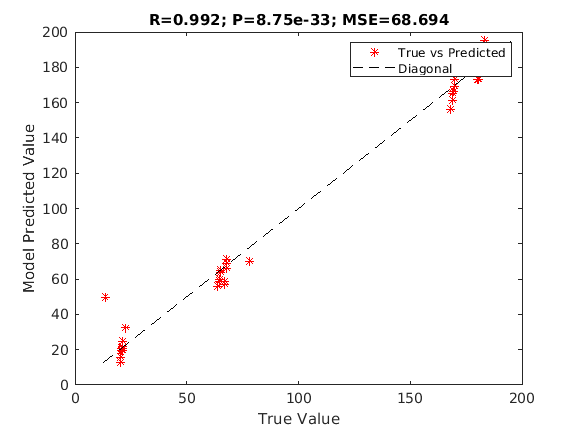

pdct_partslm = predict(mdl, test_x);
EstimationErrorPlot(pdct_partslm, test_y);

## Using Regression Tree

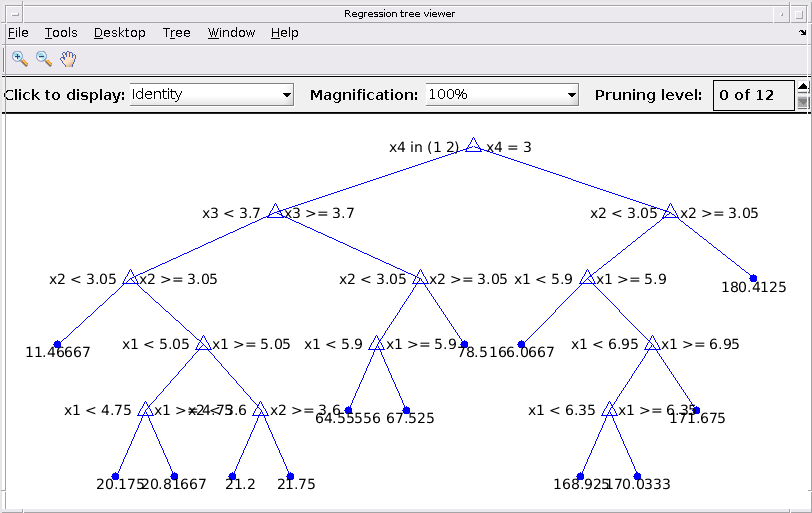

mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4]);
view(mdl, 'Mode', 'graph');

### Hyper parameter Tuning

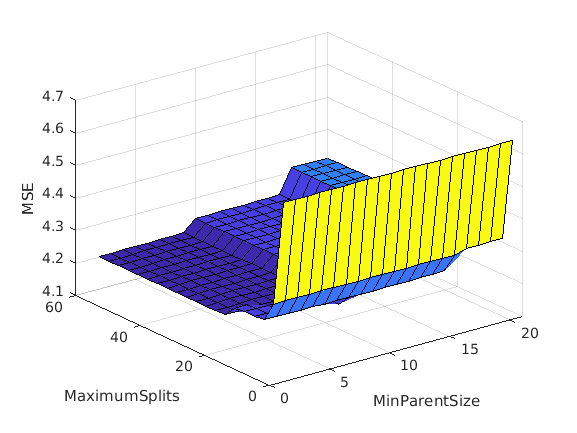

%mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4], "MaxNumSplits",3,"MinParentSize",2);
%MinParentSize how many training observations must contribute to the learning process for each decision node
err = zeros(20,20);
for i=1:20
    for j=1:20
        mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4], "MaxNumSplits",3*i,"MinParentSize",j+1);
        pdct_tree = predict(mdl, validate_x);
        err(i,j) = mean((pdct_tree - validate_y).^2);
    end
end
figure(3);
surf(2:21,3*[1:20],log(err));
xlabel("MinParentSize");
ylabel("MaximumSplits");
zlabel("MSE");

%We can use the log function, which can compress larger heights of the surface and make a lower minima easier to visualize.

### Find the minimum error

[i, j] = find(err==min(err(:)));
mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4], "MaxNumSplits",3*i(1),"MinParentSize",j(1)+1);

### Use Tuned Model

pdct_tree = predict(mdl, test_x);
figure(4);

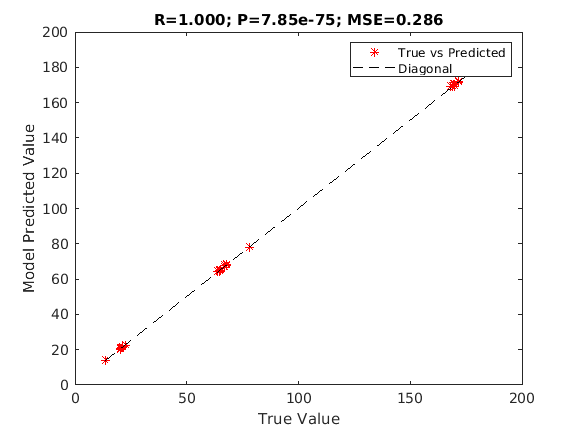

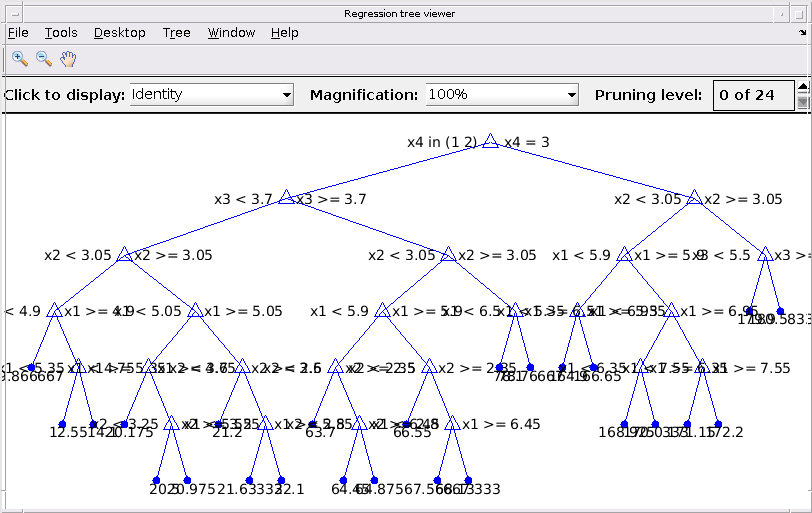

EstimationErrorPlot(pdct_tree, test_y);
view(mdl, 'Mode', 'graph');

## Cross-Validation loss

The term loss often refers to the error function for machine learning classification and regression methods. Cross-validation is a process by which different splits of the dataset are created to iteratively choose training and testing sets for error analysis. Often, this process leads to an estimation of the error, that is more robust than simply choosing a single training testing set split, as we did in our example above

cvmdl = fitrtree([train_x; test_x], [train_y; test_y], "CategoricalPredictors", [4], "MaxNumSplits",3*i(1),"MinParentSize",j(1)+1);
rng(0);
cvloss(cvmdl);% Because this is a stochastic operation, initailize the random generator to get repeatable result
%returns an MSE equal to 0.38

## Polynomial Relation Sample

nonlinear_y = features(:,1).^1.5 + features(:,2).^2 + exp(features(:,3)) + s.^0.5 + randn(150,1);
train_y = nonlinear_y(1:2:end);
validate_y = nonlinear_y(2:4:end);
test_y = nonlinear_y(4:4:end);

### Try Stepwise regression

mdl = stepwiselm(train_x, train_y,"constant","Upper","linear","CategoricalVars",[4]);

1. Adding x1, FStat = 109.1664, pValue = 3.805234e-16
2. Adding x4, FStat = 14.5095, pValue = 5.2089e-06
3. Adding x3, FStat = 38.2827, pValue = 3.64803e-08
4. Adding x2, FStat = 8.8103, pValue = 0.0041152


pdct = predict(mdl, test_x);
figure(5);
subplot(2,2,1);
EstimationErrorPlot(pdct, test_y);
ylabel("Stepwise with linear terms");
%Stepwise with non-linear terms
mdl = stepwiselm(train_x, train_y,"CategoricalVars",[4]);

1. Adding x1, FStat = 109.1664, pValue = 3.805234e-16
2. Adding x4, FStat = 14.5095, pValue = 5.2089e-06
3. Adding x1:x4, FStat = 25.1696, pValue = 6.18411e-09
4. Adding x3, FStat = 32.7103, pValue = 2.61216e-07
5. Adding x1:x3, FStat = 263.636, pValue = 6.458695e-25
6. Adding x3:x4, FStat = 8.3391, pValue = 0.00059736


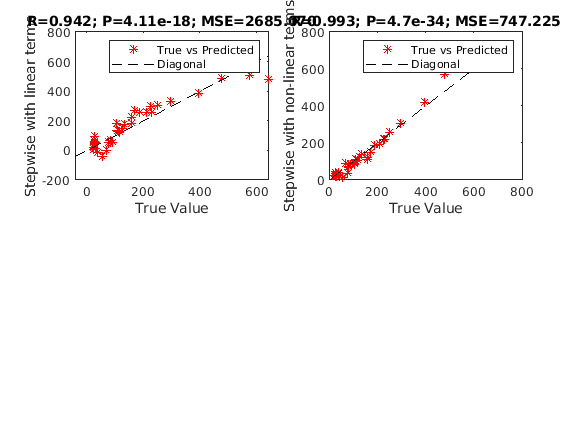

pdct = predict(mdl, test_x);
subplot(2,2,2);
EstimationErrorPlot(pdct, test_y);
ylabel("Stepwise with non-linear terms");

### Using MATLAB's built in Hyperparameter training process

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      9.6194 |     0.26744 |      9.6194 |      9.6194 |           21 |


|    2 | Best   |      9.3593 |    0.070264 |      9.3593 |      9.4159 |            8 |


|    3 | Best   |      8.9921 |    0.056364 |      8.9921 |      8.9921 |            1 |


|    4 | Accept |      8.9935 |     0.10465 |      8.9921 |       8.992 |            3 |


|    5 | Best   |       8.992 |    0.077253 |       8.992 |      8.9793 |            2 |


|    6 | Accept |       8.992 |    0.033422 |       8.992 |       8.992 |            2 |


|    7 | Accept |      8.9921 |    0.032782 |       8.992 |       8.992 |            1 |


|    8 | Accept |      8.9921 |    0.034505 |       8.992 |      8.9921 |            1 |


|    9 | Accept |       8.992 |    0.035269 |       8.992 |       8.992 |            2 |


|   10 | Accept |      8.9921 |    0.036719 |       8.992 |      8.9921 |            1 |


|   11 | Accept |       8.992 |    0.033586 |       8.992 |       8.992 |            2 |


|   12 | Accept |      10.451 |    0.037077 |       8.992 |       8.992 |           56 |


|   13 | Accept |      9.2326 |    0.034122 |       8.992 |       8.992 |            5 |


|   14 | Accept |      9.3834 |    0.032329 |       8.992 |       8.992 |           13 |


|   15 | Accept |      9.8976 |    0.032155 |       8.992 |       8.992 |           34 |


|   16 | Accept |      8.9935 |    0.032526 |       8.992 |       8.992 |            3 |


|   17 | Accept |      9.0069 |     0.04163 |       8.992 |      8.9921 |            4 |


|   18 | Accept |      9.4574 |    0.040159 |       8.992 |      8.9909 |           10 |


|   19 | Accept |      8.9935 |    0.033464 |       8.992 |       8.992 |            3 |


|   20 | Accept |      9.5865 |    0.032923 |       8.992 |      8.9888 |           17 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      8.9935 |    0.035022 |       8.992 |      8.9909 |            3 |


|   22 | Accept |      9.0069 |    0.031897 |       8.992 |       8.992 |            4 |


|   23 | Accept |      10.009 |     0.03625 |       8.992 |       8.992 |           44 |


|   24 | Accept |      9.2784 |    0.033288 |       8.992 |       8.992 |            6 |


|   25 | Accept |      9.7891 |    0.047765 |       8.992 |       8.992 |           27 |


|   26 | Accept |      9.3354 |    0.031708 |       8.992 |       8.992 |            7 |


|   27 | Accept |      9.4484 |    0.033054 |       8.992 |       8.992 |           15 |


|   28 | Accept |      9.4783 |    0.034584 |       8.992 |       8.992 |           11 |


|   29 | Accept |       9.712 |    0.032682 |       8.992 |       8.992 |           24 |


|   30 | Accept |      9.9645 |    0.044294 |       8.992 |       8.992 |           39 |


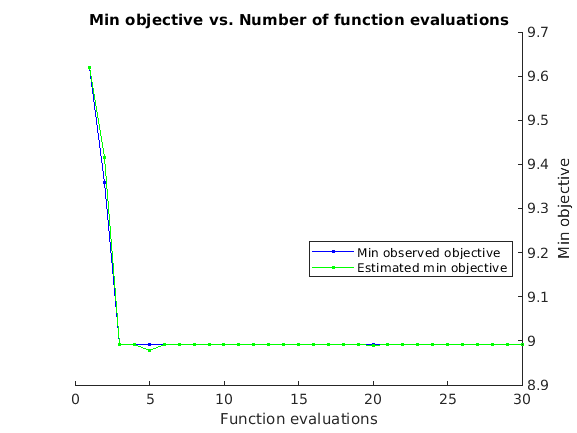

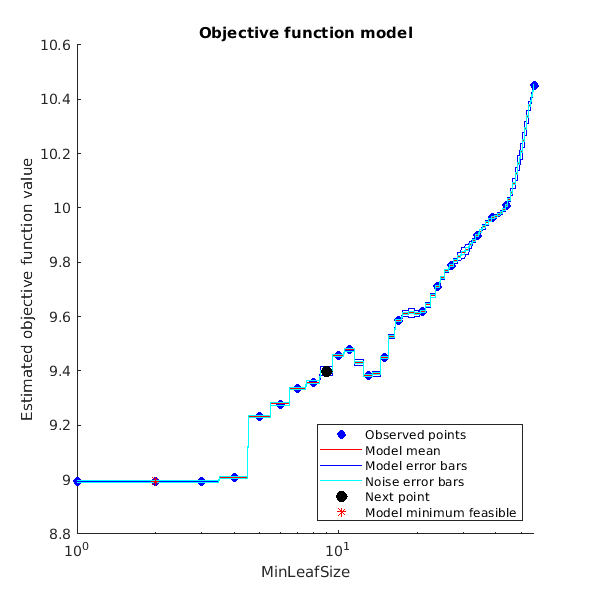


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 57.0897 seconds
Total objective function evaluation time: 1.4592

Best observed feasible point:
    MinLeafSize
    ___________

         2     

Observed objective function value = 8.992
Estimated objective function value = 8.992
Function evaluation time = 0.077253

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

         2     

Estimated objective function value = 8.992
Estimated function evaluation time = 0.041603



mdl = fitrtree([train_x; validate_x], [train_y; validate_y], "CategoricalPredictors", [4], "OptimizeHyperparameters","auto");

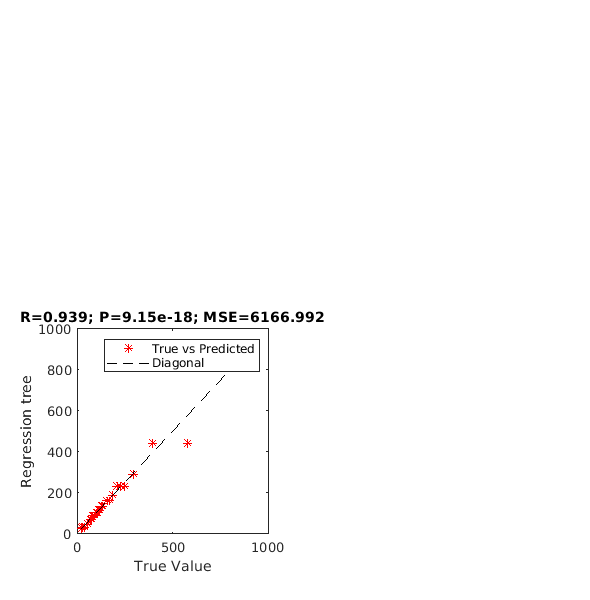

%Automatically selects the best hyperparameters using cross-validation
%approach
pdct = predict(mdl,test_x);
subplot(2,2,3);
EstimationErrorPlot(pdct,test_y);
ylabel("Regression tree");

## Gaussian Process Regression(Good for non-linear)

This approach aims to fit a network of multidimensional Gaussian radial basis functions, to the input dataset

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.5836 |      0.7463 |      5.5836 |      5.5836 |       27.204 |


|    2 | Best   |      3.3464 |     0.40564 |      3.3464 |      3.5575 |     0.086078 |


|    3 | Accept |      3.3464 |     0.41552 |      3.3464 |      3.3466 |   0.00090487 |


|    4 | Accept |      10.391 |     0.44359 |      3.3464 |      3.9586 |       969.84 |


|    5 | Accept |      3.3464 |     0.44073 |      3.3464 |       3.346 |    0.0092359 |


|    6 | Accept |      3.3464 |     0.96196 |      3.3464 |      3.3454 |    0.0001001 |


|    7 | Accept |      3.3464 |     0.80246 |      3.3464 |      3.3405 |       0.3629 |


|    8 | Accept |      3.3464 |     0.44797 |      3.3464 |      3.3397 |   0.00027104 |


|    9 | Accept |      3.3464 |     0.33584 |      3.3464 |      3.3377 |      0.17395 |


|   10 | Accept |      3.3464 |     0.28966 |      3.3464 |      3.3376 |    0.0027955 |


|   11 | Accept |      3.3464 |     0.32539 |      3.3464 |      3.3404 |      0.17928 |


|   12 | Accept |      3.3464 |      0.5468 |      3.3464 |      3.3406 |   0.00010028 |


|   13 | Accept |      3.3464 |     0.35682 |      3.3464 |      3.3406 |     0.025419 |


|   14 | Accept |      3.3464 |     0.53774 |      3.3464 |      3.3421 |      0.17657 |


|   15 | Accept |      3.3464 |     0.42623 |      3.3464 |      3.3422 |   0.00026803 |


|   16 | Accept |      3.3464 |     0.34715 |      3.3464 |      3.3422 |    0.0047672 |


|   17 | Accept |      3.3464 |     0.32735 |      3.3464 |      3.3422 |    0.0014333 |


|   18 | Accept |      3.5538 |     0.32924 |      3.3464 |      3.3469 |       2.3921 |


|   19 | Accept |      3.3464 |     0.34372 |      3.3464 |      3.3469 |       0.5882 |


|   20 | Accept |      3.3464 |     0.33168 |      3.3464 |      3.3433 |      0.52865 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      3.3464 |     0.36993 |      3.3464 |      3.3434 |     0.042095 |


|   22 | Accept |      3.3464 |     0.34458 |      3.3464 |      3.3434 |     0.014695 |


|   23 | Accept |      3.3464 |     0.32989 |      3.3464 |      3.3435 |   0.00059367 |


|   24 | Accept |      3.3464 |     0.37111 |      3.3464 |      3.3439 |      0.44468 |


|   25 | Accept |      3.3464 |     0.31627 |      3.3464 |       3.344 |   0.00016993 |


|   26 | Accept |      3.3464 |      0.2795 |      3.3464 |       3.344 |     0.052669 |


|   27 | Accept |      3.3464 |      0.3487 |      3.3464 |       3.344 |     0.002787 |


|   28 | Accept |      3.3464 |     0.28504 |      3.3464 |      3.3445 |      0.49294 |


|   29 | Accept |      3.3464 |     0.41604 |      3.3464 |      3.3445 |   0.00010001 |


|   30 | Accept |      3.3464 |     0.34599 |      3.3464 |      3.3445 |    0.0068701 |


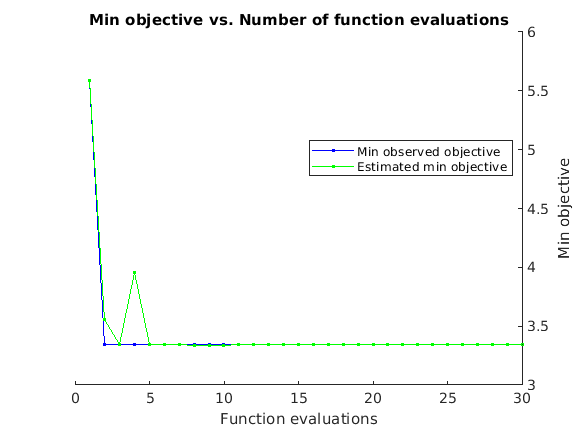

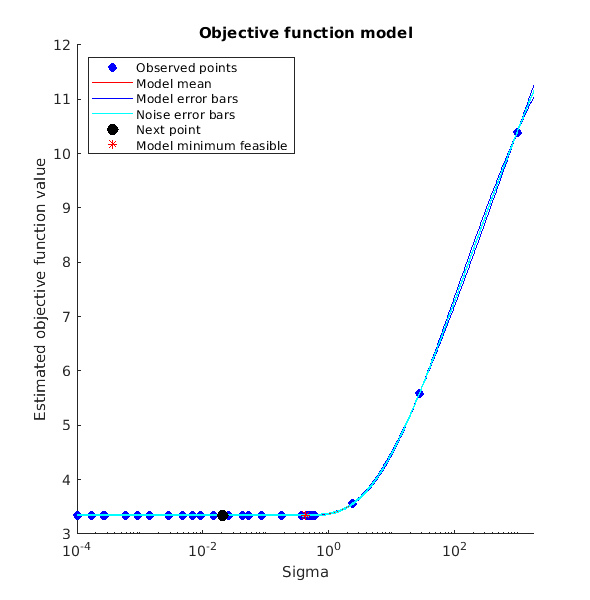


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 56.9618 seconds
Total objective function evaluation time: 12.5688

Best observed feasible point:
     Sigma  
    ________

    0.086078

Observed objective function value = 3.3464
Estimated objective function value = 3.347
Function evaluation time = 0.40564

Best estimated feasible point (according to models):
     Sigma 
    _______

    0.44468

Estimated objective function value = 3.3445
Estimated function evaluation time = 0.39708



mdl = fitrgp([train_x; validate_x], [train_y; validate_y], "FitMethod", "sr", "OptimizeHyperparameters","auto");

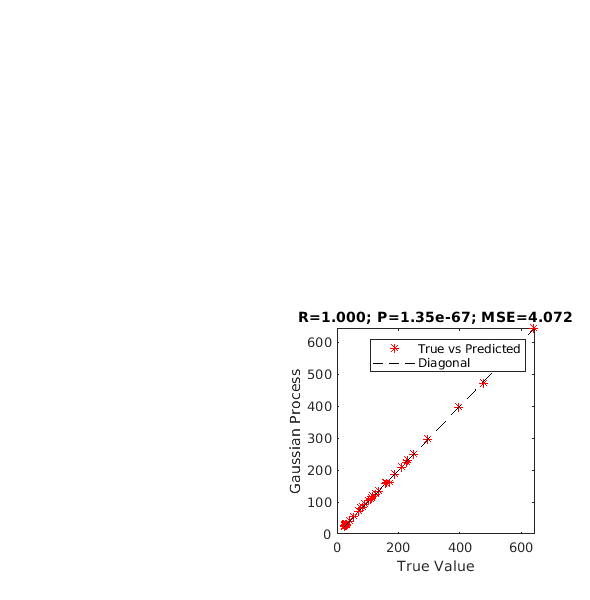

pdct = predict(mdl, test_x);
subplot(2,2,4);
EstimationErrorPlot(pdct,test_y);
ylabel("Gaussian Process");